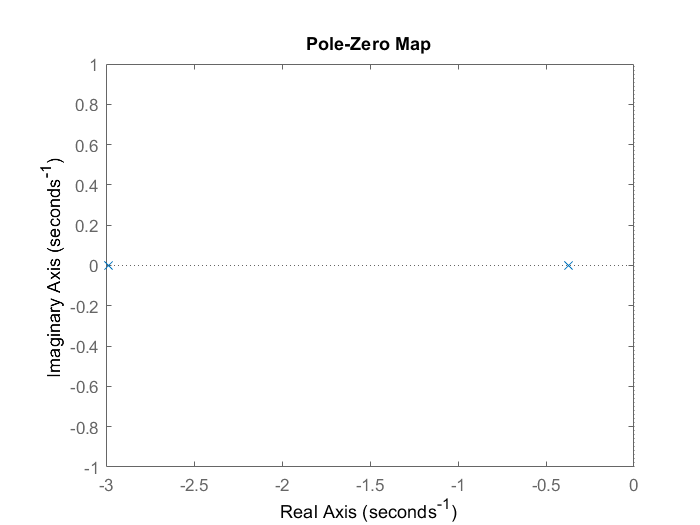

% Pole placement using LQR method 

clc;
num=[1];
den=[10 2 5];
[A,B,C,D]=tf2ss(num,den);
p1=[-4+4i -4-4i];
k1=acker(A,B,p1);
k2=acker(A,B,[-4+i -4-i]);
eig(A-B*k2);
%getting k from lqr
Q=[10 0;0 1];
R1=1;
R2=.01;
k3=lqr(A,B,Q,R1);
k4=lqr(A,B,Q,R2);
sysnew3=ss(A-B*k3,B,C,D);
pzmap(sysnew3)

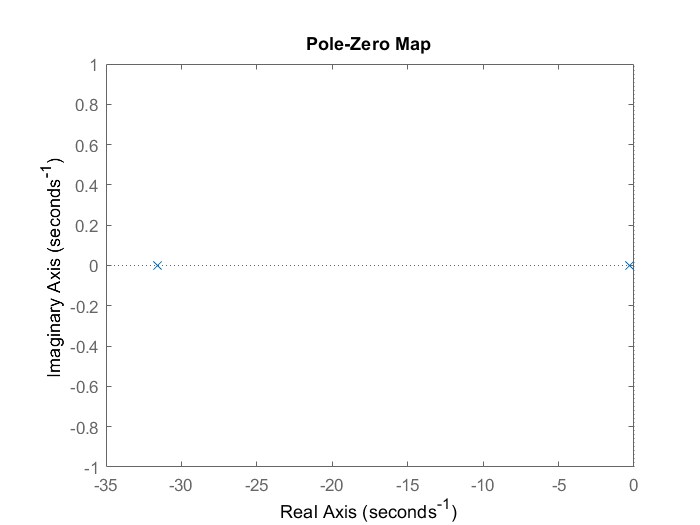

sysnew4=ss(A-B*k4,B,C,D);
pzmap(sysnew4)

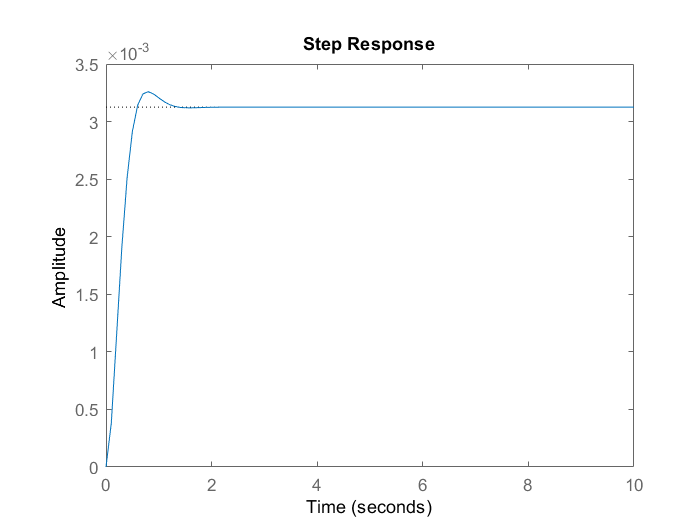

sysnew=ss(A-B*k1,B,C,D);
sysnew2=ss(A-B*k2,B,C,D); %new system after pole placemaent of k2
t=0:.1:10;
step(sysnew,t);

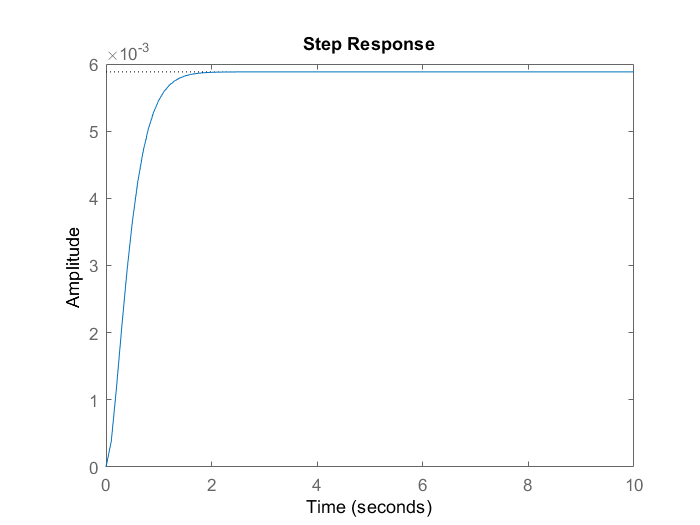

step(sysnew2,t);

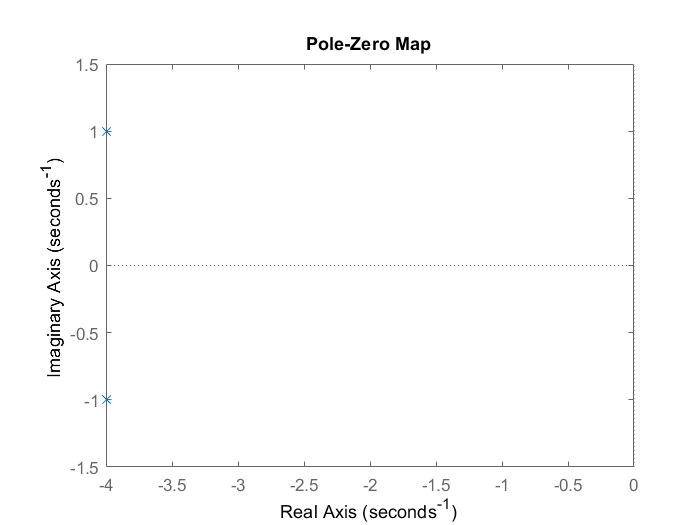

pzmap(sysnew2)%pole er map